#### Phase 4: Reduce the size of Pipe 2

Adding matlab path to: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_Three_Pipes
r_sensor=2 mm
Q_inlet_CNN=5 uL/min
height_pipe=36 um
c_Tartrazine_exp=0.08455 mol/L


c_max = 1

c_inlet=0.001 mol/L


mu = 9.9792e-04

D_coeff=4.9e-10 m^2/s


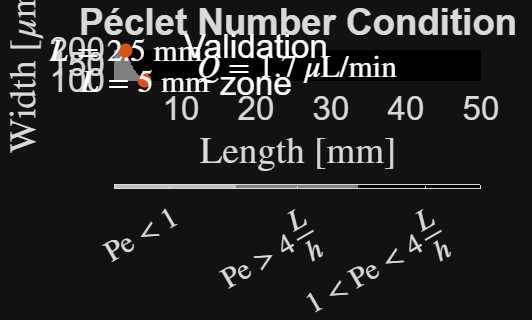

ans = 26.1799

w_Pipe_min=942.4778 um
w_Pipe_min=1 mm


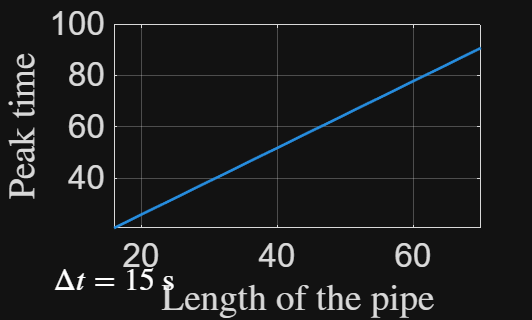

L_1 = 0.0160

L_2 = 0.0231

L_3 = 0.0345

    branch      L_m         Q_m3s          v_ms         Pe       Deff_m2s     t_pred_s    t_target_s
    ______    ________    __________    __________    ______    __________    ________    __________

      1       0.015223    3.6468e-11      0.001013    74.425    1.4061e-08       15           15    
      2       0.021519    2.5798e-11    0.00071661    52.649    7.2813e-09       30           30    
      3       0.026351    2.1067e-11     0.0005852    42.994    5.0188e-09       45           45    



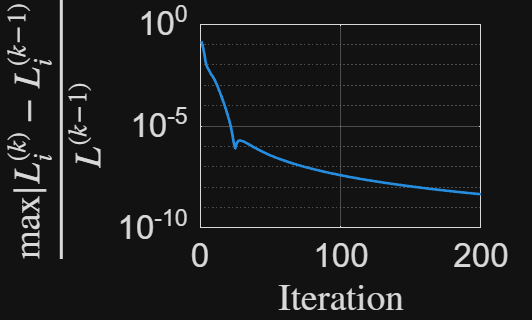

V_sensor/V_CNN =19.9173 %


v_char = 7.7160e-04

Pe = 56.6893

D_eff = 8.3635e-09

v_char = 7.7160e-04

Pe = 56.6893

D_eff = 8.3635e-09

v_char = 7.7160e-04

Pe = 56.6893

D_eff = 8.3635e-09

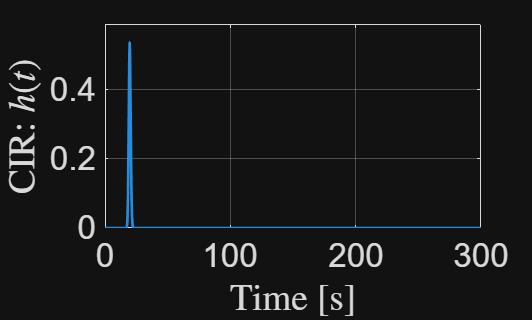

w_0=98.99500000 umL_0=0.21000000 mm

Pu311_x = -2.5869e-04

Pu333_x = 0.0155

Adding matlab path to: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_Three_Pipes
r_sensor=2 mm
Q_inlet_CNN=5 uL/min
height_pipe=36 um
c_Tartrazine_exp=0.08455 mol/L


c_max = 1

c_inlet=0.001 mol/L


mu = 9.9792e-04

D_coeff=4.9e-10 m^2/s


time_delta = 0.0100

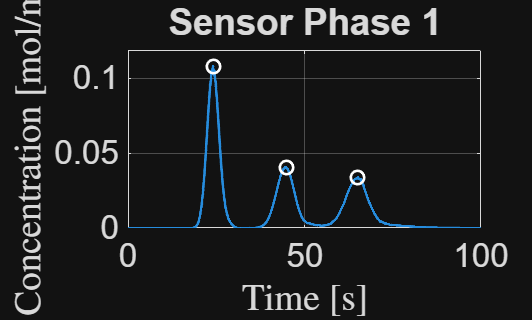

time_delta = 0.0100

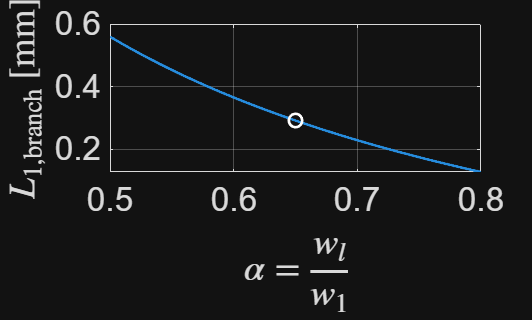

w_0=98.99500000 umL_0=0.21000000 mm

Pb33_x = 0.0143

Pu311_x = -2.5869e-04

Pu333_x = 0.0155

time_delta = 0.0100

Po4 =     0.0065    0.0008


area_rem = -1.0588e-22

length_inlet = 0.0048

Synthesis_Three_Pipes_Phase_3


%Main parameters
alpha_outlet=0.65; % reduces the width of the connected load to Pipe 1, the less the value, the highest the concentration towards the Sensor
                  % This value is found aiming to control the a amplitude of peak 1 in COMSOL

time_delta=0.01%following the COMSOL simulation for the Phase 1

time_delta = 0.0100

#### Load CNN

%Loading the area evaluated at COMSOL
% Specify the CSV file
csvFileName = 'area_reactor.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
Table_area=readtable(csvFileName,opts);
area_reactor=(Table_area.Var1(2));

% Specify the CSV file
csvFileName = 'area_sensor.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
Table_area=readtable(csvFileName,opts);
area_sensor=(Table_area.Var1(2));

% Specify the CSV file
csvFileName = 'width_inlet_reactor.csv'; %width of the inlet reactor from the CNN
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
Table_area=readtable(csvFileName,opts);
width_inlet_reactor=str2double(cell2mat(Table_area.Var1(3)));
width=alpha_outlet*width_inlet_reactor;

% Specify the CSV file
csvFileName = 'width_inlet_2_reactor.csv';%width of the inlet to the reactor from the top
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
Table_area=readtable(csvFileName,opts);
width_2=str2double(cell2mat(Table_area.Var1(3)));


% Specify the CSV file
csvFileName = 'area_Inlet_Reactor.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
Table_area=readtable(csvFileName,opts);
area_Inlet_Reactor=str2double(cell2mat(Table_area.Var1(3)));


%Po1
% Po1=[Pb12(1) (Pb11(2)+Pb12(2))/2];
Po1=Pb13;

% %Po2
Po2=Po1+[0 width];

%Po3
%evaluating the area to cover by the outlet
%height of the rectangle
b=Po2(2)-Po1(2);
%width of the rectangle
a=area_reactor/width;
Po3=[Po2(1)-a Po2(2)];

%Po4
Po4=[Po3(1) Po1(2)]

Po4 =     0.0065    0.0008



%Evaluating the side of the square
a_square=sqrt(area_sensor);
%Po5
Po5=Po4-[a_square 0];

%Po6
Po6=Po5+[0 a_square];

%Po7
Po7=Po4+[0 a_square];

Po7_x=Po7(1);
Po7_y=Po7(2);

Po6_x=Po6(1);
Po6_y=Po6(2);

%Inlet
length_inlet=area_Inlet_Reactor/width

length_inlet = 0.0048

Pinlet_1=Po2-[length_inlet 0];
Pinlet_2=Pinlet_1-[width_2 0];

Pinlet_1_x=Pinlet_1(1);
Pinlet_1_y=Pinlet_1(2);
Pinlet_2_x=Pinlet_2(1);
Pinlet_2_y=Pinlet_2(2);

%Pipe 1 Load polygon
% Stack all vertices row by row
coords = [Po1; Po2; Po3; Po7; Po6; Po5; Po1];
%saving in the CSV file
outputFile = fullfile(pwd, 'datasets', 'pipe_1_load_Phase_3.csv'); % build full path safely
writematrix(coords, outputFile);


Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, Po7_x, "m", "Po7_x");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, Po7_y, "m", "Po7_y");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, Po6_x, "m", "Po6_x");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, Po6_y, "m", "Po6_y");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, Pinlet_1_x, "m", "Pinlet_1_x");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, Pinlet_1_y, "m", "Pinlet_1_y");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, Pinlet_2_x, "m", "Pinlet_2_x");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, Pinlet_2_y, "m", "Pinlet_2_y");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

#### Reducing the size of Pipe 2

Description: This block reduces the height of pipe 2 by folding the inner and outer side of the pipe 2 triangle. To depict the folded triangle this code follows the steps

- The height of inner line is determined as half the height of the inner triangle, that is (h2-w2/2)/2

- The point Pb22 is mirrored with the line Inner line.

- The points Pb211 and Pb231 are found with the intersection of the inner line with the lines Pb21 and Pb23.

%computing the inner line
alpha_pipe_2=0.6;%denotes the percentage of the height of the pipe 2 that will be reduced in size

Inner_line=-(alpha_pipe_2*h_2-w_2/2);

%computing the distance from the inner line to Pb22
d_inner=Pb22(2)-Inner_line;

%Pb211
Pb221=Pb22-[0 2*d_inner];

%evaluating the intercept of the inner line with line Pb21 to Pb22
m=(Pb22(2)-Pb21(2))/(Pb22(1)-Pb21(1))

m = -0.9991

%Pb211
Pb211(2)=Inner_line;
Pb211(1)=Pb21(1)+(Inner_line-Pb21(2))/m;

%evaluating the intercept of the inner line with line Pb22 to Pb23
m=(Pb23(2)-Pb22(2))/(Pb23(1)-Pb22(1))

m = 0.9991

%Pb211
Pb231(2)=Inner_line;
Pb231(1)=Pb22(1)+(Inner_line-Pb22(2))/m;

%Bottom polygon
% Stack all vertices row by row
coords = [Pb21; Pb211; Pb221; Pb231; Pb23; Pb21];
%saving in the CSV file
outputFile = fullfile(pwd, 'datasets', 'polygon_bottom_Phase_4.csv'); % build full path safely
writematrix(coords, outputFile);


#### Outer Polygon

Description: The new points on the outer side (bottom polygon) are evaluated with fixed distance to the already calculated innter points Pb211, Pb221, and Pb231

%Evaluating the distance between Pb22 and Pu22
d_width=Pb22(2)-Pu22(2);
%Pu211
Pu211=Pb211-[0 d_width];
%Pu221
Pu221=Pb221-[0 d_width];
%Pu213
Pu213=Pb231-[0 d_width];

%Outer polygon 
% Stack all vertices row by row
coords = [Pu31; Pu32; Pu33; Pu23; Pu213; Pu221; Pu211; Pu21; Pu31];
%saving in the CSV file
outputFile = fullfile(pwd, 'datasets', 'polygon_outer_Phase_4.csv'); % build full path safely
writematrix(coords, outputFile);

%===============Helpers========================

function writeComsolParamCSV(filename, T)
    % Writes the 3-column cell array back to CSV
    writetable(T, filename, "Delimiter", ",","WriteVariableNames", false);
end


function T = upsertParamFromVar(T, var, unit, desc)
%UPSERTPARAMFROMVAR Upsert a COMSOL parameter row using MATLAB variable name.
%
% Usage:
%   T = upsertParamFromVar(T, myVar, "mol/m^3", "Description");
%   T = upsertParamFromVar(T, myVar, "",        "Description");  % no unit

    name = inputname(2);
    if isempty(name)
        error("upsertParamFromVar: Could not infer variable name. Use upsertParamTable with explicit name.");
    end

    % If unit is omitted or passed as empty, treat as no-unit
    if nargin < 3 || isempty(unit) || (isstring(unit) && strlength(unit)==0) || ...
                     (ischar(unit) && strlength(string(unit))==0)
        unit = "";
    end

    % Desc can be omitted too
    if nargin < 4 || isempty(desc)
        desc = "";
    end

    T = upsertParamTable(T, string(name), var, unit, desc);
end


function T = upsertParamTable(T, name, value, unit, desc)
%UPSERTPARAMTABLE Insert or overwrite a parameter row (name, expr, desc)
% in a 3-column table T.

    name = string(name);

    % Normalize unit/desc robustly
    unit = normalizeTextScalar(unit);
    desc = normalizeTextScalar(desc);

    expr = buildComsolExpr(value, unit);

    % Find existing entry in first column
    idx = find(string(T{:,1}) == name, 1, "first");

    if isempty(idx)
        % Append new row (assign all columns)
        newRow = {name, expr, desc};
        T = [T; cell2table(newRow, "VariableNames", T.Properties.VariableNames)];
    else
        % Overwrite existing row
        T{idx,1} = name;
        T{idx,2} = expr;
        T{idx,3} = desc;
    end
end


function expr = buildComsolExpr(value, unit)
%BUILDCOMSOLPR Build "value[unit]" or "value" if unit is empty.

    unit = normalizeTextScalar(unit); % ensures "" if empty/whitespace/etc.

    if isnumeric(value)
        if ~isscalar(value)
            error("buildComsolExpr: value must be scalar for COMSOL parameters.");
        end
        valStr = string(num2str(value, "%.15g"));
    else
        valStr = string(value); % keep expressions as text
    end

    if strlength(unit) == 0
        expr = valStr;
    else
        expr = valStr + "[" + unit + "]";
    end
end


function s = normalizeTextScalar(x)
%NORMALIZETEXTSCALAR Convert x to a clean string scalar.
% - [] / missing / whitespace-only -> ""
% - char/string -> trimmed string scalar

    if nargin == 0 || isempty(x)
        s = "";
        return;
    end

    % Handle missing string
    if isstring(x) && isscalar(x) && ismissing(x)
        s = "";
        return;
    end

    s = string(x);
    if numel(s) ~= 1
        error("Expected a single unit/description text value, got %d elements.", numel(s));
    end

    s = strtrim(s);
    if ismissing(s)
        s = "";
    end
end